%clear all
clc
%set variables
Model.Nx=2000;                      % number of grid points in the x (row) direction
Model.Ny=1024;                       % number of grid points in the y (column) direction
Model.dx= 3.75e-05;                % grid point spacing in the x direction [m]
Model.dy= 3.75e-05;                % grid point spacing in the y direction [m]
Model.sample_rate_model=1e9/5;        %[HZ]
Model.sample_rate_exp=1e9/5;          %[HZ]
Model.amplitude=1;
Medium.speed_of_sound=1480; %speed of sound in a homogeneous medium should be the same as the model[m/s]
Medium.sound_speed_sample=1490;%speed of sound inside the sample
Medium.density_sample=1040;%density of the sample
Medium.absorption=206;               %[1/m]
Geometry.l=0.019;                    %diameter of transducer
Geometry.sensor_thikness=3.75e-05; %thikness of the sensor
Geometry.distance=0.02645;%distance between the back of cuvette and transducer[m].
Geometry.cuvette_length=0.0055;%Width of the sample inside the cuvette
Geometry.cuvette_face=5e-3;   %thickness of PMMA layer
Geometry.cuvette_Gasket=0.5e-3   % thickness of silicon rubber

Geometry = struct with fields:
                   l: 0.0190
     sensor_thikness: 3.7500e-05
            distance: 0.0265
      cuvette_length: 0.0055
        cuvette_face: 0.0050
      cuvette_Gasket: 5.0000e-04
    cuvette_diameter: 0.0180
                   a: 1.1600


Geometry.cuvette_diameter=0.018; % diameter of the sample inside the cylindrical cuvette.[m]
Geometry.a=1.16;


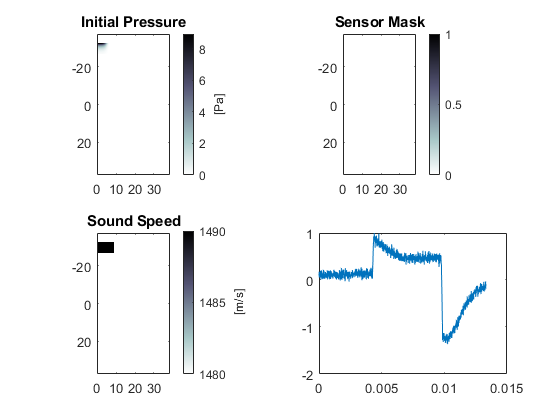

%read experimental data from TDMS files
filename = 'C:\Users\Marzieh\Documents\Marzieh\Data\19.07.2023\CUSO40.25M.19.7.2023_blue_ND0.6_test1_20230719_94819_541.tdms';
my_tdms_struct = TDMS_getStruct(filename,1);
channels=my_tdms_struct.M670D0;
S_exp=Mean_Tdms(channels);
figure(20)
plot(0:1/Model.sample_rate_exp*Medium.speed_of_sound:(length(S_exp)-1)*Medium.speed_of_sound/Model.sample_rate_exp,S_exp/max(S_exp(:)))

%S_exp=smoothdata(S_exp,'movmean',50);


Running k-Wave simulation...
  start time: 06-Sep-2023 10:39:58
  reference sound speed: 1480m/s
  dt: 5ns, t_end: 40us, time steps: 8001
  input grid size: 2000 by 1024 grid points (75 by 38.4mm)
  maximum supported frequency: 19.7333MHz
  smoothing p0 distribution...
  casting variables to gpuArray type...
  precomputation completed in 1.516s
  starting time loop...
  estimated simulation time 3min 37.9472s...
  GPU memory used: 2.0641 GB (of 11.9998 GB)
  simulation completed in 4min 18.5351s
  total computation time 4min 20.091s


sensor_data_integrated =    1.0e-15 *

    0.0792    0.0641    0.0675    0.0801    0.0918    0.0870    0.0767    0.0658    0.0691    0.0607    0.0377    0.0446    0.0426    0.0531    0.0482    0.0169    0.0056   -0.0198   -0.0280   -0.0370   -0.0308   -0.0055    0.0034    0.0069    0.0430    0.1139    0.1372    0.1558    0.1562    0.1029    0.0301   -0.0029   -0.0335   -0.0193    0.0297    0.0659    0.1327    0.2029    0.2402    0.2682    0.2501    0.2367    0.1868    0.1203    0.0399    0.0036   -0.0382   -0.0795   -0.0916   -0.0633


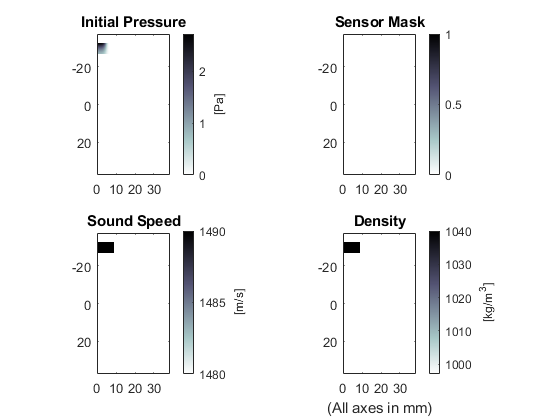

global source;
global sensor_data;
global sensor;
global medium;
S_model=forward_homogeneous(Model, Medium, Geometry);

%Run the forward model to get simulated data.
medium_m=medium;
sensor_m=sensor;
source_m=source;
data_m=sensor_data;
%signal_m=S_model;

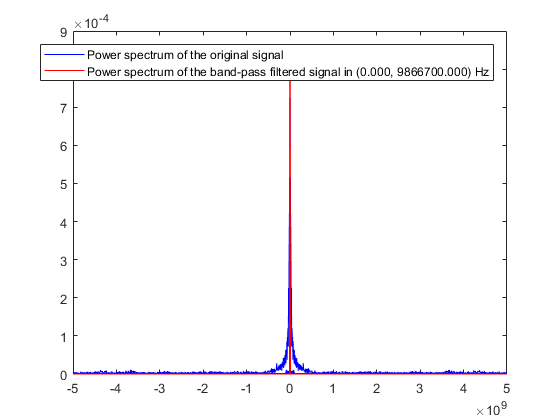

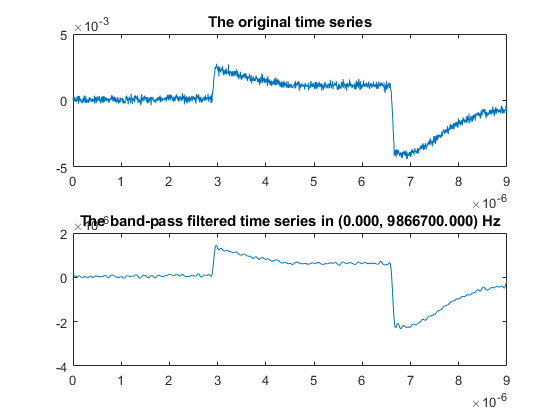

%apply rectangular frequency filter
lower_limit=0;         %lower limit for the frequency filter[HZ]
higher_limit=9866700;         %higher limit for the frequency filter[HZ]
S_model_filteredd = bpfilt(S_exp,lower_limit,higher_limit,Model.sample_rate_exp);

[S_model_processed, S_exp_processed] =processsignals_alternative(S_model,S_exp, Model, Medium, Geometry);
%process both experimental and simulated data to compare them. 
%steps of the process:
%1_ match sample rates of experimental and simulated data.
%3_ correct offset of experimental signal.
%4_ match time delays of experimental and simulated signals
%5_ normalizing simulated data based on experimental data.


%Error calculation
global X_exp_pos
global X_model_pos
global Y_exp_pos
global Y_model_pos

RMSE_total=sqrt(mean((S_exp_processed-S_model_processed).^2))/sqrt(mean((S_exp_processed).^2))*100;
RMSE_pos=sqrt(mean((Y_exp_pos-Y_model_pos).^2))/sqrt(mean((Y_exp_pos).^2))*100;
peak_to_peak_amplitude=abs(min(S_exp_processed(:))-min(S_model_processed(:)))/abs(min(S_exp_processed(:)))*100;



%visualizatoin
global X_exp
global X_model
global p_0

figure(11)
plot(X_model, S_model_processed);
hold on
plot(X_exp, S_exp_processed/0.8);

ylabel('PA signal');
xlabel('X [m]');
title({['RMSE total=',num2str(RMSE_total),'%             RMSE positive part=',num2str(RMSE_pos),'%'],...
    ['peak to peak amplitude error= ',num2str(peak_to_peak_amplitude),'%...' ...
    '      absorption coefficient=',num2str(Medium.absorption)]});

legend('Simulated PA signal','Experimental PA signal', 'Location','southeast')



figure(10)
plot(X_exp_pos,Y_exp_pos)
hold on
plot(X_model_pos,Y_model_pos)
%plot(X_exp_pos,fitresult(X_exp_pos))
%plot(X_model_pos,fitresultm(X_model_pos))
%title({['absorption coefficient fitted exp=',num2str(coeffvals(1,2))],...
   % ['absorption coefficient fitted model=',num2str(coeffvalsm(1,2))]})
%legend('experimental data','simulated data', 'experimental fit', 'simulated fit')

